## **Opening the simulation**

open_system("MotorControlRL")

## **Create the Environment**

% Observation info
obsInfo = rlNumericSpec([2 1],LowerLimit=[-inf 0  ]',UpperLimit=[inf inf]');

% Name and description are optional and not used by the software
obsInfo.Name = "observations";
obsInfo.Description = "integrated error, error, and measured speed";

% Action info
actInfo = rlNumericSpec([1 1]);
actInfo.Name = "flow";

Create the environment object.

env = rlSimulinkEnv("MotorControlRL","MotorControlRL/RL Agent",obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

%env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts =1;
Tf= 200;

Fix the random generator seed for reproducibility.

rng(0)

## **Create the Critic**

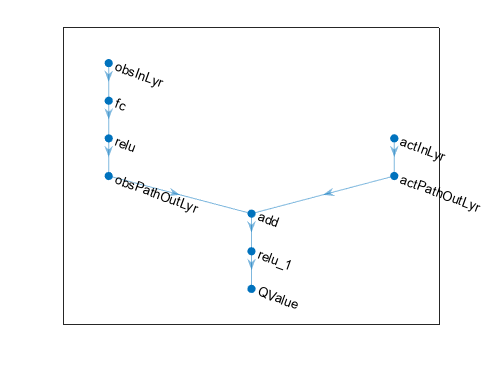


% Observation path
obsPath = [
    featureInputLayer(obsInfo.Dimension(1),Name="obsInLyr")
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(25,Name="obsPathOutLyr")
    ];

% Action path
actPath = [
    featureInputLayer(actInfo.Dimension(1),Name="actInLyr")
    fullyConnectedLayer(25,Name="actPathOutLyr")
    ];

% Common path
commonPath = [
    additionLayer(2,Name="add")
   reluLayer
    fullyConnectedLayer(1,Name="QValue")
    ];

%criticNetwork = layerGraph();
%criticNetwork = addLayers(criticNetwork,obsPath);
%criticNetwork = addLayers(criticNetwork,actPath);
%criticNetwork = addLayers(criticNetwork,commonPath);

%criticNetwork = connectLayers(criticNetwork,"obsPathOutLyr","add/in1");
%criticNetwork = connectLayers(criticNetwork,"actPathOutLyr","add/in2");


criticNetwork1 = layerGraph();
criticNetwork1 = addLayers(criticNetwork1,obsPath);
criticNetwork1 = addLayers(criticNetwork1,actPath);
criticNetwork1 = addLayers(criticNetwork1,commonPath);

criticNetwork1 = connectLayers(criticNetwork1,"obsPathOutLyr","add/in1");
criticNetwork1 = connectLayers(criticNetwork1,"actPathOutLyr","add/in2");

criticNetwork2 = layerGraph();  % Create a second critic network (identical structure)
criticNetwork2 = addLayers(criticNetwork2,obsPath);
criticNetwork2 = addLayers(criticNetwork2,actPath);
criticNetwork2 = addLayers(criticNetwork2,commonPath);

criticNetwork2 = connectLayers(criticNetwork2,"obsPathOutLyr","add/in1");
criticNetwork2 = connectLayers(criticNetwork2,"actPathOutLyr","add/in2");

% Convert critic networks to dlnetwork objects
criticNetwork1 = dlnetwork(criticNetwork1);
criticNetwork2 = dlnetwork(criticNetwork2);

% Create critic approximators (one for each network)
critic1 = rlQValueFunction(criticNetwork1,obsInfo,actInfo,ObservationInputNames="obsInLyr",ActionInputNames="actInLyr");
critic2 = rlQValueFunction(criticNetwork2,obsInfo,actInfo,ObservationInputNames="obsInLyr",ActionInputNames="actInLyr");


figure
plot(criticNetwork)



figure
plot(criticNetwork)

View the critic network configuration.


%figure
%plot(criticNetwork)

Convert the network to a `dlnetwork` object and summarize its properties.

%criticNetwork = dlnetwork(criticNetwork);
%summary(criticNetwork)

Create the critic approximator object using the specified deep neural network, the environment specification objects, and the names if the network inputs to be associated with the observation and action channels.

%critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,ObservationInputNames="obsInLyr",ActionInputNames="actInLyr");

Check the critic with a random input observation and action

%getValue(critic, ...
    %{rand(obsInfo.Dimension)}, ...
    %{rand(actInfo.Dimension)})

## **Create the Actor**

Define the network as an array of layer objects.

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(3)
    tanhLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];

Convert the network to a `dlnetwork` object and summarize its properties.

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 13

   Inputs:
      1   'input'   2 features



Create the actor approximator object using the specified deep neural network, the environment specification objects, and the name if the network input to be associated with the observation channel.

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

Check the actor with a random input observation.

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.8107]}


## **Create the DDPG Agent**

Create the DDPG agent using the specified actor and critic approximator objects.

%agent = rlDDPGAgent(actor,critic); 
AgentOptions = rlTD3AgentOptions;
agent = rlTD3Agent(actor, critic1,AgentOptions);

Specify options for the agent, the actor, and the critic using dot notation.

%agent.SampleTime = Ts;

%agent.AgentOptions.TargetSmoothFactor = 1e-3;
%agent.AgentOptions.DiscountFactor = 1.0;
%agent.AgentOptions.MiniBatchSize = 64;
%agent.AgentOptions.ExperienceBufferLength = 1e6; 

%agent.AgentOptions.NoiseOptions.Variance = 0.3;
%agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

%agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
%agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
%agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
%agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

Check the agent with a random input observation

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.0418]}


## **Train Agent**

trainOpts = rlTrainingOptions(MaxEpisodes=10000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress", ...
    StopTrainingCriteria="AverageReward", ...
    StopTrainingValue=800);

Train the agent using the [`train`](https://in.mathworks.com/help/reinforcement-learning/ref/rl.agent.rlqagent.train.html) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.


%doTraining = true;

%if doTraining
    % Train the agent.
%    trainingStats = train(agent,env,trainOpts);
%else
    % Load the pretrained agent for the example.
  %  load("WaterTankDDPG.mat","agent")
%end

trainingStats = train(agent,env,trainOpts);

## **Validate Trained Agent**

[sldebug('MotorControlRL') ](matlab:sldebug(bdroot);)

Validate the learned agent against the model by simulation. Since the reset function randomizes the reference values, fix the random generator seed to ensure simulation reproducibility.

rng(1)

Simulate the agent within the environment, and return the experiences as output.

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
experiences = sim(env,agent,simOpts);

## **Local Reset Function**

function in = localResetFcn(in)

% Randomize reference signal
blk = sprintf("MotorControlRL/SpeedStep");
refSpeedValues = [-1,-0.8,-0.6,-0.4,-0.2,-0.1,-0.07,-0.04,-0.01,0.01,0.04,0.07,0.1,0.2,0.4,0.6,0.8,1];
idx = randperm(length(refSpeedValues),2);
refspeed1 = refSpeedValues(idx(1))*1500;
refspeed2 = refSpeedValues(idx(2))*1500;
in = setBlockParameter(in,blk,'Time','100');
in = setBlockParameter(in,blk,'Before',num2str(refspeed1));
in = setBlockParameter(in,blk,'After',num2str(refspeed2));
end
